# Генерация и формирование сигнала

В данной модели происходит генерирование радиосигнала с определенной модуляцией. Модель учитывает нестабильность частоты генератора, а также шумовые искажения амплитуд сигнала.

## 1. Генерация радиоимпульса

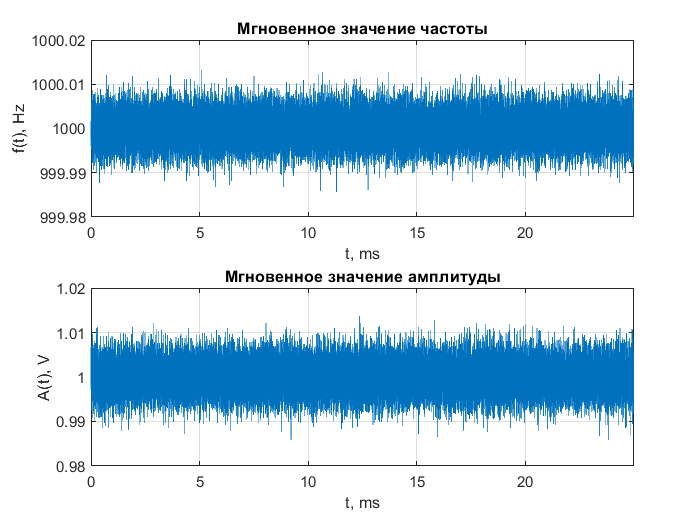

clear; close all;

A0 = 1;                                 % амплитуда
f0 = 1e3;                               % несущая частота
fs = 2e3*f0;                            % частота дискретизации
dt = 1/fs;                              % период дискретизации
t  = 0:dt:25/f0-dt;                     % сетка времени

fv = 1e-5;                              % нестабильность частоты генератора
deltaf = f0*fv/3*randn(1,length(t));    % мгновенное изменение частоты
Av = 1e-2;                              % нестабильность амплитуды колебаний
deltaA = A0*Av/3*randn(1,length(t));    % мгновенное изменение амплитуды
A  = A0 + deltaA;                       % мгновенная амплитуда
phi    = 2*pi*f0*t+2*pi*deltaf;         % полная фаза
s  = A.*cos(phi);                       % радиоимпульс

t = t*1e3;
figure;
subplot(2,1,1);
plot(t,f0+deltaf); xlim([t(1), t(end)]);
xlabel('t, ms'); ylabel('f(t), Hz');
title('Мгновенное значение частоты'); grid on;
subplot(2,1,2);
plot(t,A); xlim([t(1), t(end)]);
xlabel('t, ms'); ylabel('A(t), V');
title('Мгновенное значение амплитуды'); grid on;

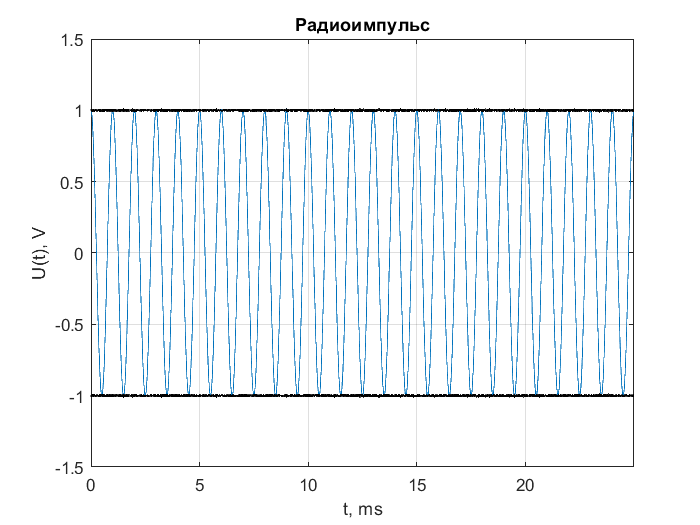


figure;
plot(t,s); xlim([t(1), t(end)]);
xlabel('t, ms'); ylabel('U(t), V');
title('Радиоимпульс'); grid on;
line(t,A,'Color','Black','LineStyle','--');
line(t,-A,'Color','Black','LineStyle','--');

t = t*1e-3;

## 2. Формирование АМ радиоимпульса

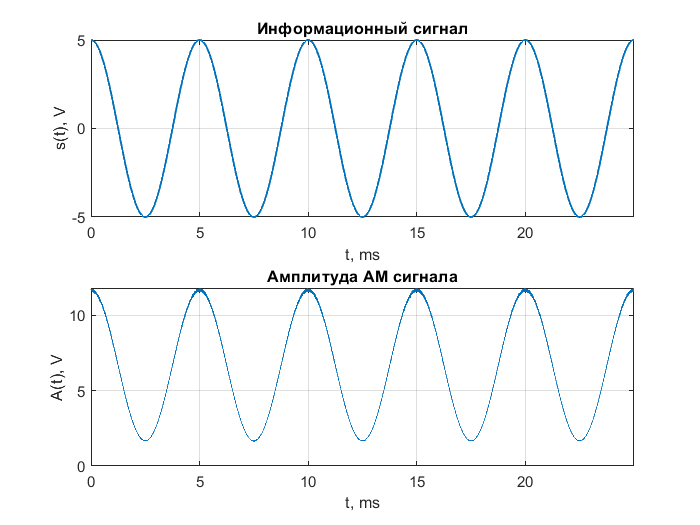

A0 = 5;                             % амплитуда информационного сигнала
F  = 200;                           % частота информационного сигнала
Ma = 0.75;                          % индекс (глубина) модуляции
Av = 1e-2;                          % нестабильность амплитуды колебаний
Ai = A0*cos(2*pi*F*t);              % информационный сигнал
A  = A0/Ma+Ai;                      % приподнятый информационный сигнал
An = 1 + Av/3*randn(1,length(t));   % мгновенная амплитуда несущего колебания
A  = A.*An;                         % амплитуда АМ сигнала
s  = A.*cos(phi);                   % АМ сигнал

t = t*1e3;
figure;
subplot(2,1,1);
plot(t,Ai,'LineWidth',1); xlim([t(1), t(end)]);
xlabel('t, ms'); ylabel('s(t), V');
title('Информационный сигнал'); grid on;
subplot(2,1,2);
plot(t,A); xlim([t(1), t(end)]);
xlabel('t, ms'); ylabel('A(t), V');
title('Амплитуда АМ сигнала'); grid on;

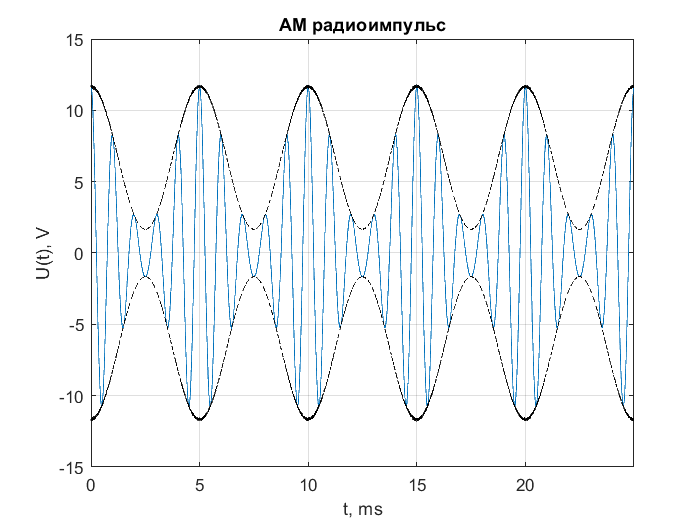


figure;
plot(t,s); xlim([t(1), t(end)]);
xlabel('t, ms'); ylabel('U(t), V');
title('АМ радиоимпульс'); grid on;
line(t,A,'Color','Black','LineStyle','--');
line(t,-A,'Color','Black','LineStyle','--');

t = t*1e-3;

## 3. Формирование ЧМ радиоимпульса

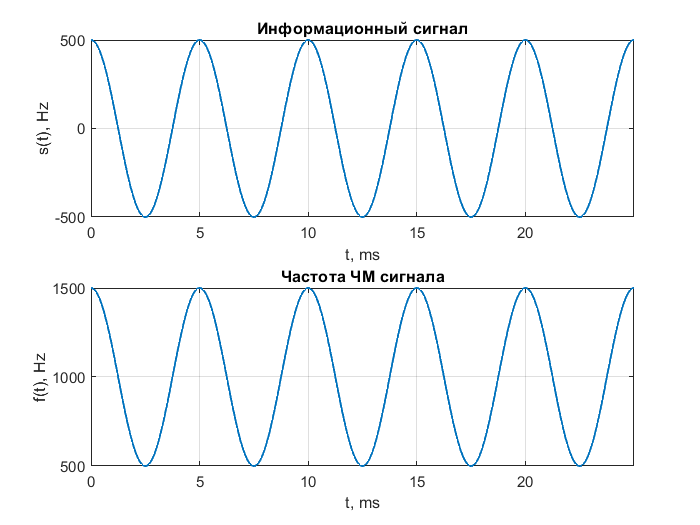

A0  = 1;                                        % амплитуда
A   = A0 + deltaA;                              % мгновенная амплитуда
Fd  = 500;                                      % девиация частоты
Mf  = Fd/F;                                     % индекс (глубина) частотной модуляции
fi  = cos(2*pi*F*t);                            % информационный сигнал
f   = f0 + Fd*fi;                               % мгновенное значение частоты
phi = 2*pi*f0*t+Mf*sin(2*pi*F*t)+2*pi*deltaf;   % полная фаза
s   = A.*cos(phi);                              % ЧМ сигнал

t = t*1e3;
figure;
subplot(2,1,1);
plot(t,fi*Fd,'LineWidth',1); xlim([t(1), t(end)]);
xlabel('t, ms'); ylabel('s(t), Hz');
title('Информационный сигнал'); grid on;
subplot(2,1,2);
plot(t,f,'LineWidth',1); xlim([t(1), t(end)]);
xlabel('t, ms'); ylabel('f(t), Hz');
title('Частота ЧМ сигнала'); grid on;

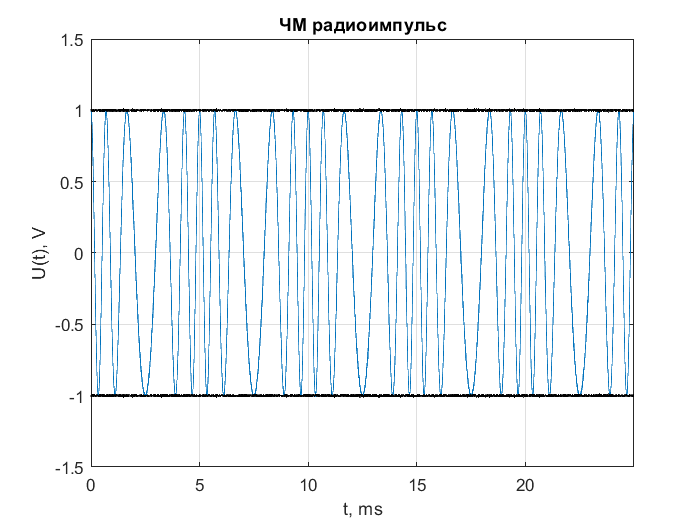


figure;
plot(t,s); xlim([t(1), t(end)]);
xlabel('t, ms'); ylabel('U(t), V');
title('ЧМ радиоимпульс'); grid on;
line(t,A,'Color','Black','LineStyle','--');
line(t,-A,'Color','Black','LineStyle','--');

t = t*1e-3;

## 4. Формирование АМ-ЧМ радиоимпульса

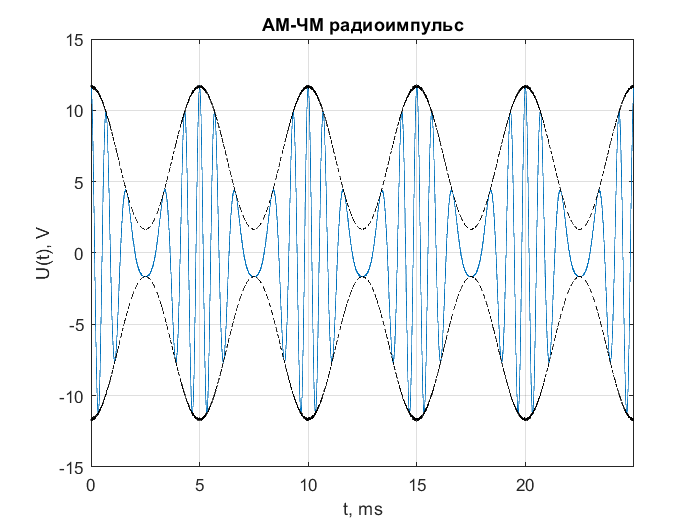

A0 = 5;             % амплитуда информационного сигнала
A  = A0/Ma+Ai;      % приподнятый информационный сигнал
A  = A.*An;         % амплитуда АМ сигнала
s  = A.*cos(phi);   % АМ-ЧМ сигнал

t = t*1e3;
figure;
plot(t,s); xlim([t(1), t(end)]);
xlabel('t, ms'); ylabel('U(t), V');
title('АМ-ЧМ радиоимпульс'); grid on;
line(t,A,'Color','Black','LineStyle','--');
line(t,-A,'Color','Black','LineStyle','--');

t = t*1e-3;